%% OFDM vs OCDM vs OTFS vs AFDM BER comparison with theoretical BER
% Channel selector:
%   channelType = 0 -> AWGN
%   channelType = 1 -> high-mobility multipath Rayleigh fading
%
% Interpretation:
%   In AWGN, all four unitary waveforms have the same BER.
%   In high-mobility multipath Rayleigh fading, this script uses
%   literature-backed effective assumptions:
%     OFDM: Doppler-sensitive, single effective branch plus ICI.
%     OCDM: chirp spreading gives more robustness than OFDM.
%     OTFS: delay-Doppler processing gives near-full path diversity.
%     AFDM: DAFT-domain path separation gives full path diversity.
%
% This is a performance-level BER comparison, not a complete physical
% detector implementation for every waveform.

clear; clc; close all;
rng(7);

%% User settings
channelType = 1;          % 0 = AWGN, 1 = high-mobility multipath Rayleigh
N = 64;                   % Number of symbols per frame
numFrames = 2e4;          % Increase for smoother Monte Carlo curves
EbN0dB = 0:2:30;          % Eb/N0 range in dB
savePlot = true;          % Save PNG beside this script

% AFDM chirp parameters. In a complete AFDM receiver these are selected
% from the maximum delay and Doppler spread so distinct paths do not
% overlap in the DAFT domain.
c1 = 1 / (2 * N);
c2 = 1 / (2 * N);

% High-mobility Rayleigh assumptions used when channelType = 1.
numPaths = 4;             % Separable delay-Doppler paths
ocdmDiversity = 2;        % OCDM chirp-spreading diversity abstraction
ofdmIciCoeff = 0.04;      % Larger value means stronger Doppler ICI in OFDM
ocdmIciCoeff = 0.008;     % OCDM is less Doppler-sensitive than OFDM
otfsLossDb = 0.8;         % Practical OTFS receiver/estimation loss
afdmLossDb = 0.0;         % Ideal AFDM full-diversity reference

%% Derived quantities
bitsPerSymbol = 1;        % BPSK
EbN0lin = 10.^(EbN0dB / 10);
numBits = N * numFrames;

berOfdm = zeros(size(EbN0dB));
berOcdm = zeros(size(EbN0dB));
berOtfs = zeros(size(EbN0dB));
berAfdm = zeros(size(EbN0dB));

%% Unitary transforms for AWGN waveform simulation
n = (0:N-1).';
F = exp(-1j * 2 * pi * (n * n.') / N) / sqrt(N);

% AFDM DAFT matrix: A = Lambda_c2 * F * Lambda_c1.
LambdaC1 = diag(exp(-1j * 2 * pi * c1 * n.^2));
LambdaC2 = diag(exp(-1j * 2 * pi * c2 * n.^2));
A = LambdaC2 * F * LambdaC1;

% OCDM discrete-Fresnel-type matrix. The exact phase convention varies
% across papers; for AWGN BER, the important property is unitarity.
FresnelLeft = diag(exp(-1j * pi * n.^2 / N));
FresnelRight = diag(exp(-1j * pi * n.^2 / N));
C = FresnelLeft * F' * FresnelRight;

%% Theoretical BER
switch channelType
    case 0
        theoryOfdm = berBpskAwgn(EbN0lin);
        theoryOcdm = theoryOfdm;
        theoryOtfs = theoryOfdm;
        theoryAfdm = theoryOfdm;
        channelName = 'AWGN';

    case 1
        % OFDM is penalized by Doppler ICI. If ICI power is proportional to
        % signal power, post-ICI SINR saturates at high Eb/N0.
        gammaOfdmEff = EbN0lin ./ (1 + ofdmIciCoeff * EbN0lin);
        theoryOfdm = berBpskRayleigh(gammaOfdmEff);

        % OCDM is chirp based and more robust than OFDM, but here it is
        % modeled with partial diversity and smaller residual ICI.
        gammaOcdmEff = EbN0lin ./ (1 + ocdmIciCoeff * EbN0lin);
        theoryOcdm = berBpskRayleighMrc(gammaOcdmEff, ocdmDiversity);

        % OTFS works in the delay-Doppler domain. Here it receives full
        % path diversity with a small practical SNR loss.
        gammaOtfsEff = EbN0lin * 10^(-otfsLossDb / 10);
        theoryOtfs = berBpskRayleighMrc(gammaOtfsEff, numPaths);

        % AFDM is modeled as the ideal full-diversity chirp-domain
        % reference under DAFT-domain path separation.
        gammaAfdmEff = EbN0lin * 10^(-afdmLossDb / 10);
        theoryAfdm = berBpskRayleighMrc(gammaAfdmEff, numPaths);

        channelName = sprintf('High-Mobility %d-Path Rayleigh', numPaths);

    otherwise
        error('channelType must be 0 for AWGN or 1 for high-mobility Rayleigh.');
end

%% Monte Carlo simulation
for idx = 1:length(EbN0dB)
    gamma = EbN0lin(idx) * bitsPerSymbol;

    switch channelType
        case 0
            noiseVar = 1 / gamma;
            bits = randi([0 1], N, numFrames);
            symbols = 1 - 2 * bits;

            % Unitary waveform simulation.
            txOfdm = ifft(symbols, [], 1) * sqrt(N);
            txOcdm = C' * symbols;
            txOtfs = symbols;       % Unitary placeholder for AWGN BER.
            txAfdm = A' * symbols;

            noiseOfdm = complexNoise(N, numFrames, noiseVar);
            noiseOcdm = complexNoise(N, numFrames, noiseVar);
            noiseOtfs = complexNoise(N, numFrames, noiseVar);
            noiseAfdm = complexNoise(N, numFrames, noiseVar);

            rxOfdmSymbols = fft(txOfdm + noiseOfdm, [], 1) / sqrt(N);
            rxOcdmSymbols = C * (txOcdm + noiseOcdm);
            rxOtfsSymbols = txOtfs + noiseOtfs;
            rxAfdmSymbols = A * (txAfdm + noiseAfdm);

            berOfdm(idx) = mean((real(rxOfdmSymbols) < 0) ~= bits, 'all');
            berOcdm(idx) = mean((real(rxOcdmSymbols) < 0) ~= bits, 'all');
            berOtfs(idx) = mean((real(rxOtfsSymbols) < 0) ~= bits, 'all');
            berAfdm(idx) = mean((real(rxAfdmSymbols) < 0) ~= bits, 'all');

        case 1
            % Fast Monte Carlo abstraction for high-mobility Rayleigh.
            hOfdm = rayleighGains(1, numBits);
            gammaOfdmInst = abs(hOfdm).^2 * gamma / (1 + ofdmIciCoeff * gamma);
            pOfdmInst = qfuncFast(sqrt(2 * gammaOfdmInst));

            hOcdm = rayleighGains(ocdmDiversity, numBits);
            gammaOcdmInst = sum(abs(hOcdm).^2, 1) * ...
                gamma / (1 + ocdmIciCoeff * gamma);
            pOcdmInst = qfuncFast(sqrt(2 * gammaOcdmInst));

            hOtfs = rayleighGains(numPaths, numBits);
            gammaOtfsInst = sum(abs(hOtfs).^2, 1) * ...
                gamma * 10^(-otfsLossDb / 10);
            pOtfsInst = qfuncFast(sqrt(2 * gammaOtfsInst));

            hAfdm = rayleighGains(numPaths, numBits);
            gammaAfdmInst = sum(abs(hAfdm).^2, 1) * ...
                gamma * 10^(-afdmLossDb / 10);
            pAfdmInst = qfuncFast(sqrt(2 * gammaAfdmInst));

            berOfdm(idx) = mean(rand(1, numBits) < pOfdmInst);
            berOcdm(idx) = mean(rand(1, numBits) < pOcdmInst);
            berOtfs(idx) = mean(rand(1, numBits) < pOtfsInst);
            berAfdm(idx) = mean(rand(1, numBits) < pAfdmInst);
    end

    fprintf(['Eb/N0 = %2d dB | OFDM = %.4e | OCDM = %.4e | ' ...
        'OTFS = %.4e | AFDM = %.4e\n'], ...
        EbN0dB(idx), berOfdm(idx), berOcdm(idx), berOtfs(idx), berAfdm(idx));
end

Eb/N0 =  0 dB | OFDM = 1.4998e-01 | OCDM = 5.8439e-02 | OTFS = 1.6257e-02 | AFDM = 1.1140e-02
Eb/N0 =  2 dB | OFDM = 1.1339e-01 | OCDM = 3.3150e-02 | OTFS = 5.8156e-03 | AFDM = 3.6648e-03
Eb/N0 =  4 dB | OFDM = 8.2820e-02 | OCDM = 1.7409e-02 | OTFS = 1.7164e-03 | AFDM = 1.0039e-03
Eb/N0 =  6 dB | OFDM = 6.0034e-02 | OCDM = 8.6078e-03 | OTFS = 4.4609e-04 | AFDM = 2.8203e-04
Eb/N0 =  8 dB | OFDM = 4.3323e-02 | OCDM = 3.9875e-03 | OTFS = 1.1016e-04 | AFDM = 4.9219e-05
Eb/N0 = 10 dB | OFDM = 3.1962e-02 | OCDM = 1.8500e-03 | OTFS = 1.8750e-05 | AFDM = 1.2500e-05
Eb/N0 = 12 dB | OFDM = 2.3843e-02 | OCDM = 8.5234e-04 | OTFS = 6.2500e-06 | AFDM = 0.0000e+00
Eb/N0 = 14 dB | OFDM = 1.8958e-02 | OCDM = 4.1641e-04 | OTFS = 0.0000e+00 | AFDM = 7.8125e-07
Eb/N0 = 16 dB | OFDM = 1.5448e-02 | OCDM = 1.9375e-04 | OTFS = 0.0000e+00 | AFDM = 0.0000e+00
Eb/N0 = 18 dB | OFDM = 1.3312e-02 | OCDM = 1.0000e-04 | OTFS = 0.0000e+00 | AFDM = 0.0000e+00
Eb/N0 = 20 dB | OFDM = 1.2084e-02 | OCDM = 5.8594e-05 | OTFS

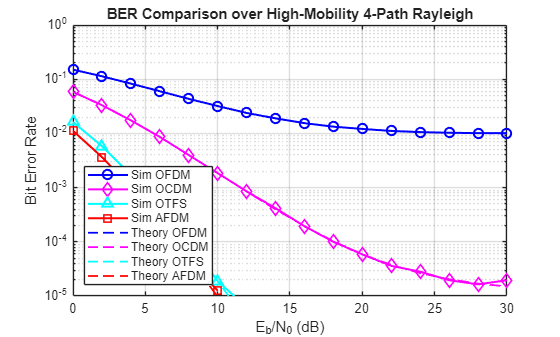

Saved plot to C:\Users\munee\AppData\Local\Temp\Editor_xtwxp\ofdm_ocdm_otfs_afdm_ber_high_mobility_4_path_rayleigh.png



%% Plot
figure('Color', 'w');
semilogy(EbN0dB, berOfdm, 'bo-', 'LineWidth', 1.5, 'MarkerSize', 7); hold on;
semilogy(EbN0dB, berOcdm, 'md-', 'LineWidth', 1.5, 'MarkerSize', 7);
semilogy(EbN0dB, berOtfs, 'c^-', 'LineWidth', 1.5, 'MarkerSize', 7);
semilogy(EbN0dB, berAfdm, 'rs-', 'LineWidth', 1.5, 'MarkerSize', 7);
semilogy(EbN0dB, theoryOfdm, 'b--', 'LineWidth', 1.3);
semilogy(EbN0dB, theoryOcdm, 'm--', 'LineWidth', 1.3);
semilogy(EbN0dB, theoryOtfs, 'c--', 'LineWidth', 1.3);
semilogy(EbN0dB, theoryAfdm, 'r--', 'LineWidth', 1.3);
grid on;

xlabel('E_b/N_0 (dB)');
ylabel('Bit Error Rate');
title(['BER Comparison over ', channelName]);
legend('Sim OFDM', 'Sim OCDM', 'Sim OTFS', 'Sim AFDM', ...
    'Theory OFDM', 'Theory OCDM', 'Theory OTFS', 'Theory AFDM', ...
    'Location', 'southwest');
xlim([min(EbN0dB) max(EbN0dB)]);
ylim([1e-5 1]);

if savePlot
    scriptDir = fileparts(mfilename('fullpath'));
    if isempty(scriptDir)
        scriptDir = pwd;
    end
    safeChannelName = lower(regexprep(channelName, '[^a-zA-Z0-9]+', '_'));
    plotFile = fullfile(scriptDir, ...
        ['ofdm_ocdm_otfs_afdm_ber_', safeChannelName, '.png']);
    exportgraphics(gcf, plotFile, 'Resolution', 200);
    fprintf('Saved plot to %s\n', plotFile);
end


%% Local functions
function z = complexNoise(rows, cols, noiseVar)
    z = sqrt(noiseVar / 2) * (randn(rows, cols) + 1j * randn(rows, cols));
end

function h = rayleighGains(rows, cols)
    h = (randn(rows, cols) + 1j * randn(rows, cols)) / sqrt(2);
end

function ber = berBpskAwgn(gamma)
    ber = 0.5 * erfc(sqrt(gamma));
end

function ber = berBpskRayleigh(gamma)
    ber = 0.5 * (1 - sqrt(gamma ./ (1 + gamma)));
end

function ber = berBpskRayleighMrc(gamma, diversityOrder)
    mu = sqrt(gamma ./ (1 + gamma));
    seriesSum = zeros(size(gamma));

    for k = 0:(diversityOrder - 1)
        coeff = nchoosek(2 * k, k);
        seriesSum = seriesSum + coeff .* ((1 - mu.^2) / 4).^k;
    end

    ber = 0.5 * (1 - mu .* seriesSum);
end

function y = qfuncFast(x)
    y = 0.5 * erfc(x / sqrt(2));
end
